clc; clearvars;

addpath(genpath("C:\Users\tely1\OneDrive - The City College of New York\Matlab Onedrive\O3_Lidar\proc_functions"))
dataPath = "C:\Users\tely1\OneDrive - The City College of New York\Matlab Onedrive\o3_lidar_data\20220720";

data_format     = "bin";
prefix = "xy";

[scaled_data,times,configs] = read_lidar_datafiles(dataPath,data_format,prefix);
scaled_data = scaled_data(1:8000,:,:,:);

times = times(:,2);
% times.TimeZone = "UTC";

num_bins = size(scaled_data,1);
num_files = size(scaled_data,2);
num_devices = size(scaled_data,3);

dz = 3.75;
h = (dz.*(1:num_bins))';
hkm = h./1000;

TR = 2;

td = 270;
data_an = scaled_data(:,:,TR,1);
data_pc = scaled_data(:,:,TR,2);
data_pc = data_pc./(1-data_pc/td);

bg_bins = 7000:8000;

bg_an = data_an(bg_bins,:);
B_an = mean(bg_an,1);

bg_pc = data_pc(bg_bins,:);
B_pc = mean(bg_pc,1);

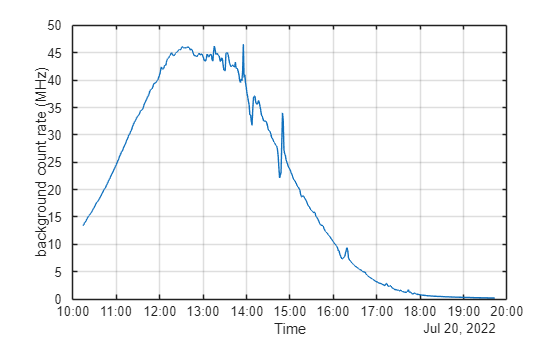

figure;
plot(times,B_pc)
xlabel('Time')
ylabel('background count rate (MHz)')
grid on

Model from Gimmestad book


$$N_B = k_R L_\lambda A  \Omega B_{opt} \tau (\lambda /hc)
$$


kR = 0.02;
A = 0.16;
omega = 0.000003;
B = 1;
tau = 2.5e-8;
lambda = 2.991e-7;

L = 0.002814873 / pi;

Nb = kR * L * A * omega * B * lambda * tau / (planckConstant * physconst('LightSpeed')) * 40;